# Question 4

## Part A

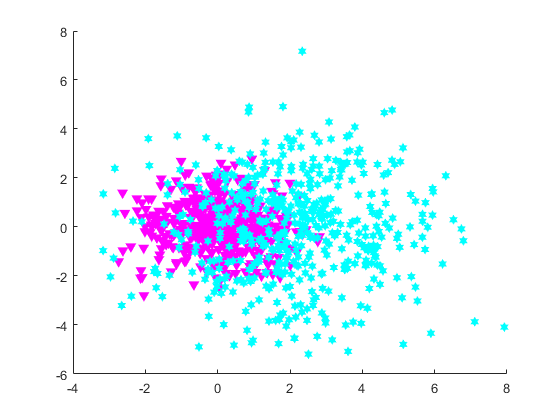

load("alldata.mat");
class = alldata(:,1);
x = alldata(:,2);
y = alldata(:,3);

figure(1)
scatter(x(1:500),y(1:500),'filled','v','MarkerFaceColor','m','MarkerEdgeColor','m')
hold on
scatter(x(501:1000),y(501:1000),'filled','h','MarkerFaceColor','c','MarkerEdgeColor','c')

% Choosing Training Data
train_data = [x(100:399) y(100:399); x(600:899) y(600:899)];
train_class = [class(100:399); class(600:899)];

% Choosing 50 test data randomly from class0
r0 = randi([1 500],50,1);
for i=1:50
    class0_test(i) = class(r0(i));
    x0_test(i) = x(r0(i));
    y0_test(i) = y(r0(i));
   
end

% Choosing 50 train data randomly from class1
r1 = randi([501 1000],50,1);
for i=1:50
    class1_test(i) = class(r1(i));
    x1_test(i) = x(r1(i));
    y1_test(i) = y(r1(i));
end

test_data = [x0_test x1_test; y0_test y1_test]';
test_class = [class0_test class1_test]';



## Naive Bayes Classifier

NB_training = fitcnb(train_data,train_class); % training NB model
train_NB = predict(NB_training,train_data); 
test_NB = predict(NB_training,test_data);

c_NB = confusionmat(test_NB,test_class) % Calculate Confusion Matrix

c_NB =     46    10
     4    40


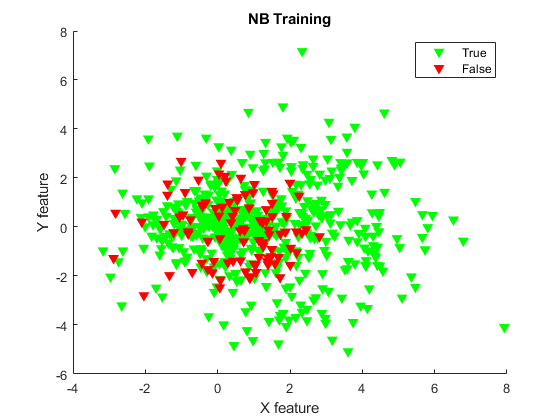


T_NB_train = find(train_NB==train_class); % True training
F_NB_train = find(train_NB~=train_class); % False training

T_NB_test = find(test_NB==test_class); %True tsesting
F_NB_test = find(test_NB~=test_class);  %True tsesting

figure(2)
scatter(train_data(T_NB_train,1),train_data(T_NB_train,2),'filled','v','MarkerFaceColor','g','MarkerEdgeColor','g')
hold on
scatter(train_data(F_NB_train,1),train_data(F_NB_train,2),'filled','v','MarkerFaceColor','r','MarkerEdgeColor','r')
xlabel('X feature')
ylabel('Y feature')
title('NB Training')
legend('True','False')

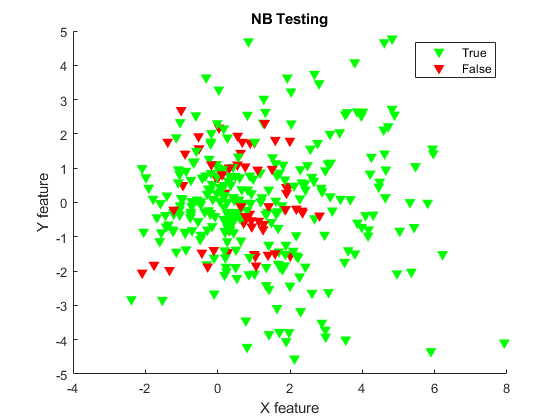


figure(3)
scatter(test_data(T_NB_test,1),test_data(T_NB_test,2),'filled','v','MarkerFaceColor','g','MarkerEdgeColor','g')
hold on
scatter(test_data(F_NB_test,1),test_data(F_NB_test,2),'filled','v','MarkerFaceColor','r','MarkerEdgeColor','r')
xlabel('X feature')
ylabel('Y feature')
title('NB Testing')
legend('True','False')

## LD Classifier

LD_training = fitclinear(train_data,train_class); % training LD model
train_LD = predict(LD_training,train_data); 
test_LD = predict(LD_training,test_data);

c_LD = confusionmat(test_LD,test_class) % Calculate Confusion Matrix

c_LD =     42    17
     8    33


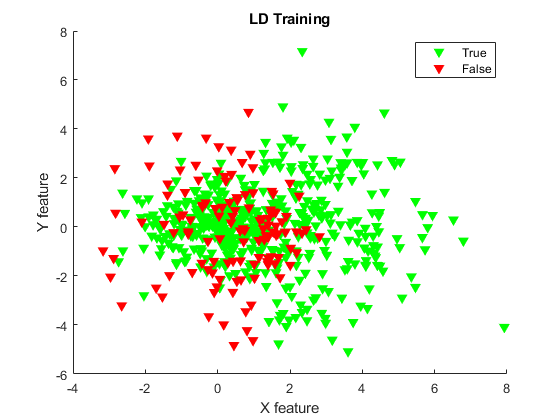


T_LD_train = find(train_LD==train_class); % True training
F_LD_train = find(train_LD~=train_class); % False training

T_LD_test = find(test_LD==test_class); %True tsesting
F_LD_test = find(test_LD~=test_class);  %True tsesting

figure(4)
scatter(train_data(T_LD_train,1),train_data(T_LD_train,2),'filled','v','MarkerFaceColor','g','MarkerEdgeColor','g')
hold on
scatter(train_data(F_LD_train,1),train_data(F_LD_train,2),'filled','v','MarkerFaceColor','r','MarkerEdgeColor','r')
xlabel('X feature')
ylabel('Y feature')
title('LD Training')
legend('True','False')

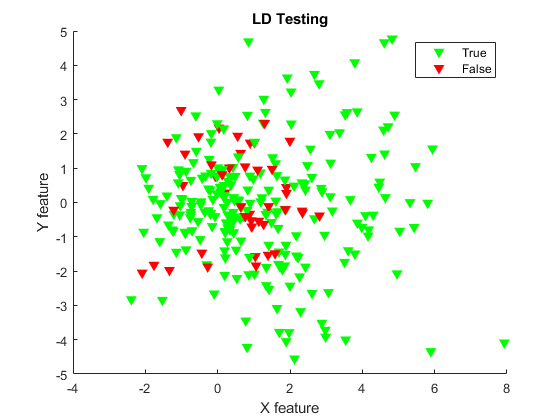


figure(5)
scatter(test_data(T_NB_test,1),test_data(T_NB_test,2),'filled','v','MarkerFaceColor','g','MarkerEdgeColor','g')
hold on
scatter(test_data(F_NB_test,1),test_data(F_NB_test,2),'filled','v','MarkerFaceColor','r','MarkerEdgeColor','r')
xlabel('X feature')
ylabel('Y feature')
title('LD Testing')
legend('True','False')

## KNN Classifier

KNN_training = fitcknn(train_data,train_class); % training KNN model
train_KNN = predict(KNN_training,train_data); 
test_KNN = predict(KNN_training,test_data);

c_KNN = confusionmat(test_KNN,test_class) % Calculate Confusion Matrix

c_KNN =     45     5
     5    45


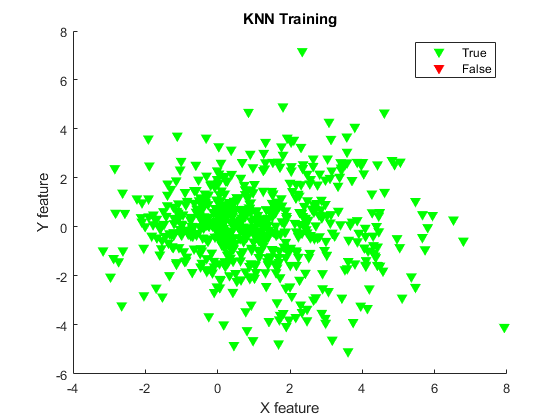


T_KNN_train = find(train_KNN==train_class); % True training
F_KNN_train = find(train_KNN~=train_class); % False training

T_KNN_test = find(test_KNN==test_class); %True tsesting
F_KNN_test = find(test_KNN~=test_class);  %True tsesting

figure(6)
scatter(train_data(T_KNN_train,1),train_data(T_KNN_train,2),'filled','v','MarkerFaceColor','g','MarkerEdgeColor','g')
hold on
scatter(train_data(F_KNN_train,1),train_data(F_KNN_train,2),'filled','v','MarkerFaceColor','r','MarkerEdgeColor','r')
xlabel('X feature')
ylabel('Y feature')
title('KNN Training')
legend('True','False')

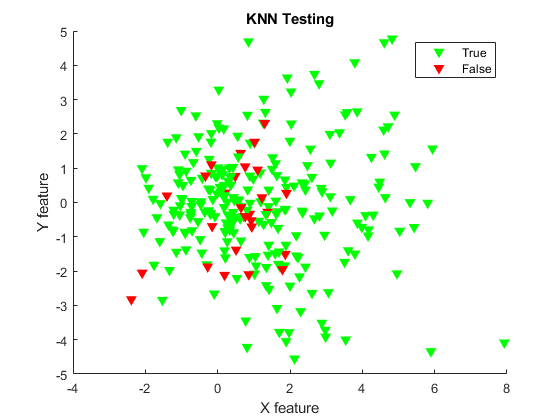


figure(7)
scatter(test_data(T_KNN_test,1),test_data(T_KNN_test,2),'filled','v','MarkerFaceColor','g','MarkerEdgeColor','g')
hold on
scatter(test_data(F_KNN_test,1),test_data(F_KNN_test,2),'filled','v','MarkerFaceColor','r','MarkerEdgeColor','r')
xlabel('X feature')
ylabel('Y feature')
title('KNN Testing')
legend('True','False')